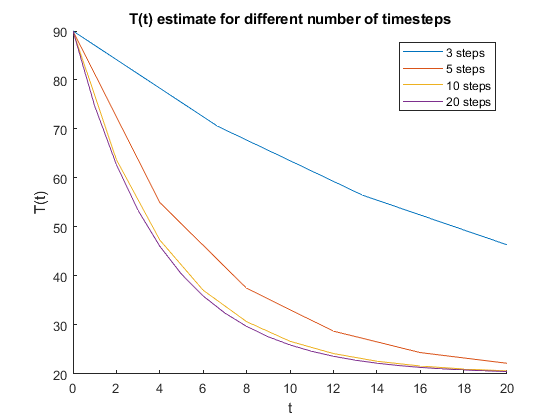

%initial value problem solver
clear;
[y,t]=IVPsolver(3);
hold on
plot(t,y,'DisplayName','3 steps')
[y,t]=IVPsolver(5);

plot(t,y,'DisplayName','5 steps')
[y,t]=IVPsolver(10);
plot(t,y,'DisplayName','10 steps')
[y,t]=IVPsolver(20);
plot(t,y,'DisplayName','20 steps')
[y' t'];
legend('show')
xlabel('t')
ylabel('T(t)')
title('T(t) estimate for different number of timesteps')

function [y,timeintervals] = IVPsolver(N)
    dt = 20/N;
    timeintervals = 0:dt:20;
    A = [-0.25 0.25];
    SOL = [NaN(1,N+1);20+zeros(1,N+1)];
    SOL(1)=90;
    for i = 2:length(timeintervals)
        SL = A*SOL(:,i-1);
        tempright = [SOL(1,i-1) + dt*SL;20];
        SR = A*tempright;
        avgS = (SL+SR)/2;
        SOL(1,i) = SOL(1,i-1) + avgS*dt;
    end
    y = SOL(1,:);
end